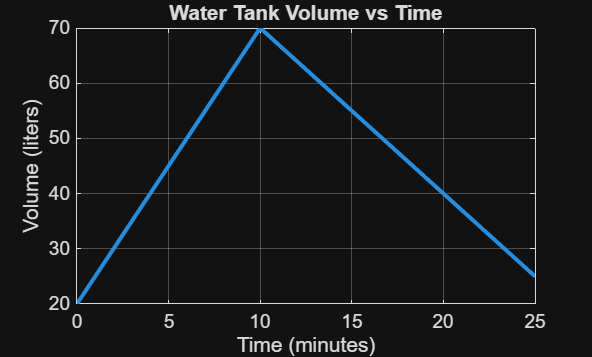

% Project 4

clc;
clear;
close all;

% 1. Time vector
t = 0:1:25;

% Initialize volume vector
V = zeros(size(t));

% Piecewise definition using logical indexing
fill_idx = (t >= 0) & (t <= 10);
drain_idx = (t > 10) & (t <= 25);

V(fill_idx) = 5*t(fill_idx) + 20;
V(drain_idx) = -3*(t(drain_idx) - 10) + 70;

% 2. Plot V(t)
figure;
plot(t, V, 'LineWidth', 2);
xlabel('Time (minutes)');
ylabel('Volume (liters)');
title('Water Tank Volume vs Time');
grid on;


% 3. Find when V = 50 liters
% Solve analytically for both phases

% Filling phase: 5t + 20 = 50 → t = 6
t_fill_50 = (50 - 20)/5;

% Draining phase: -3(t - 10) + 70 = 50 → t = 16.67
t_drain_50 = 10 + (70 - 50)/3;

% Check if within valid intervals
times_50 = [];

if t_fill_50 >= 0 && t_fill_50 <= 10
    times_50 = [times_50, t_fill_50];
end

if t_drain_50 > 10 && t_drain_50 <= 25
    times_50 = [times_50, t_drain_50];
end

% Display results
fprintf('Tank reaches 50 liters at time(s):\n');

Tank reaches 50 liters at time(s):


disp(times_50);

    6.0000   16.6667




% 4. Create table (at least 12 rows — we have 26)
T_table = table(t', V', 'VariableNames', {'Time_min', 'Volume_L'});
disp(T_table);

    Time_min    Volume_L
    ________    ________

        0          20   
        1          25   
        2          30   
        3          35   
        4          40   
        5          45   
        6          50   
        7          55   
        8          60   
        9          65   
       10          70   
       11          67   
       12          64   
       13          61   
       14          58   
       15          55   
       16          52   
       17          49   
       18          46   
       19          43   
       20          40   
       21          37   
       22          34   
       23          31   
       24          28   
       25          25   




% 5. Interpretation of slopes
fprintf('\nSlope Interpretation:\n');


Slope Interpretation:


fprintf('Filling phase slope = +5 L/min → tank is filling at 5 liters per minute.\n');

Filling phase slope = +5 L/min → tank is filling at 5 liters per minute.


fprintf('Draining phase slope = -3 L/min → tank is draining at 3 liters per minute.\n');

Draining phase slope = -3 L/min → tank is draining at 3 liters per minute.
